G - slozeni do vysledneho obrazku

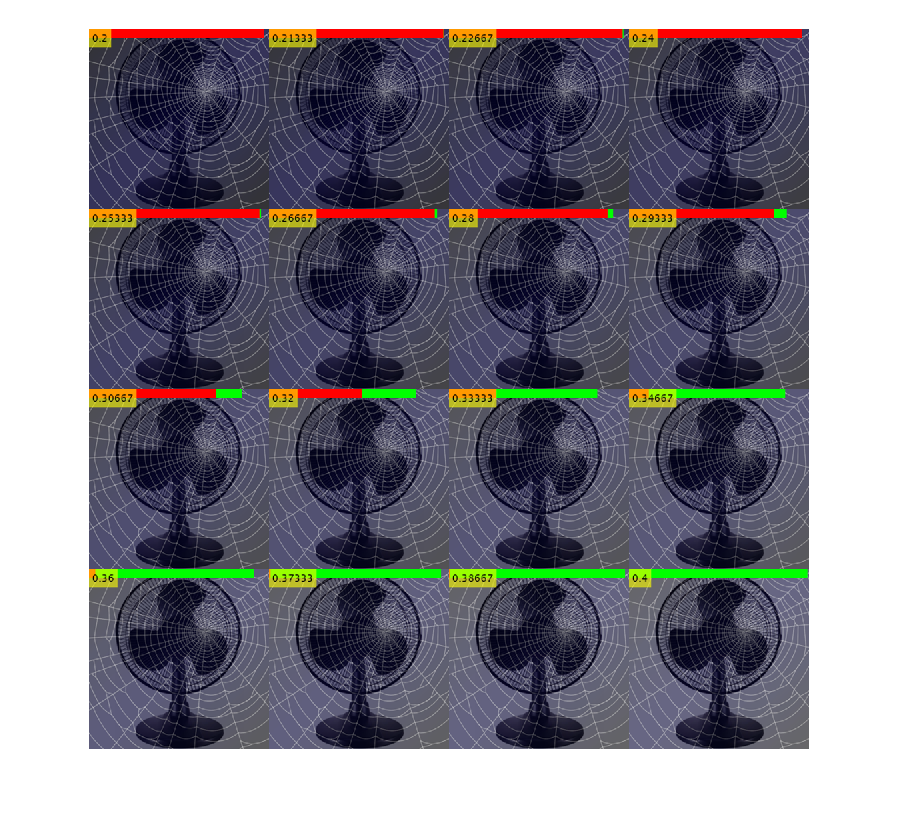

pavucina = imread("pavucina.jpg");
vetrak = imread("vetrak.jpg");

[r1, c1, d1] = size(pavucina);
[r2, c2, d2] = size(vetrak);

vetrak2 = imresize(vetrak,[r1 c1]);

alfa = linspace(0.2,0.4,16);

imageList = cell([1 16]);
j = 1;

alexNet = alexnet;

inputSize = alexNet.Layers(1).InputSize;
rows = inputSize(1);
cols = inputSize(2);

for i = 1:length(alfa)
    a = alfa(i);
    V = vetrak2.*a + pavucina.*(1-a);
    
    theImage = imresize(V, [rows cols]);
    [label, scores] = classify(alexNet, theImage);
    
    probFan = scores(546);
    probNet = scores(816);
    
    probFan = round(probFan, 3);
    probNet = round(probNet, 3);
    
    x = probFan;
    y = probNet;
    
    %[r3, c3, d3] = size(V);
    V2 = theImage;
    
    V2(1:11, 1:round(rows*y), 1) = 255;
    V2(1:11, 1:round(rows*y), 2) = 0;
    V2(1:11, 1:round(rows*y), 3) = 0;
    
    V2(1:11, round(rows*y)+1:round(rows*(x+y)), 1) = 0;
    V2(1:11, round(rows*y)+1:round(rows*(x+y)), 2) = 255;
    V2(1:11, round(rows*y)+1:round(rows*(x+y)), 3) = 0;
    
    position = [1 1];
    value = a;
    
    final = insertText(V2, position, value);
    
    imageList{j} = final;
    j = j + 1;
end

montage(imageList)

A - prolnutí

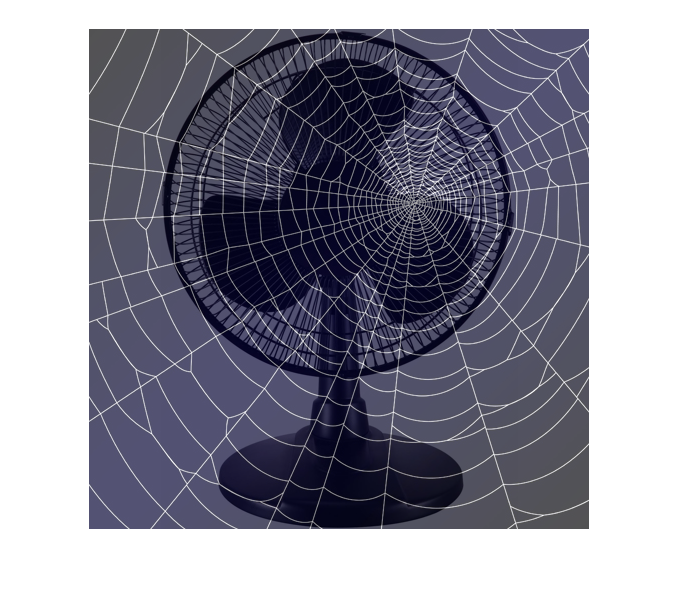

pavucina = imread("pavucina.jpg");
vetrak = imread("vetrak.jpg");

[r1, c1, d1] = size(pavucina);
[r2, c2, d2] = size(vetrak);

vetrak2 = imresize(vetrak,[r1 c1]);

size(pavucina);
size(vetrak2);

alfa = 0.32;

V = vetrak2.*alfa + pavucina.*(1-alfa);
imshow(V)

B - klasifikace obrazku

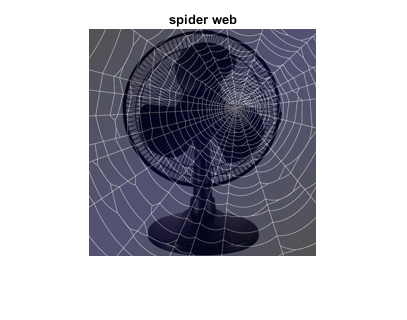

alexNet = alexnet;

inputSize = alexNet.Layers(1).InputSize;
rows = inputSize(1);
cols = inputSize(2);

theImage = imresize(V, [rows cols]);
[label, scores] = classify(alexNet, theImage);

imshow(theImage)
title(label)

C - zobrazeni pravdepodobnosti

probFan = scores(546);
probNet = scores(816);

probFan = round(probFan,3)

probFan = single
0.2990

probNet = round(probNet,3)

probNet = single
0.5170

D - klasifikacni pruh

% a = 0.6;
% b = 0.4;

x = probFan;
y = probNet;

[r3, c3, d3] = size(V);
V2 = V;

V2(1:11, 1:r3*x, 1) = 0;

V2(1:11, 1:r3*x, 2) = 255;

V2(1:11, 1:r3*x, 3) = 0;


V2(1:11, r3*x+1:r3*(x+y), 1) = 255;

V2(1:11, r3*x+1:r3*(x+y), 2) = 0;

V2(1:11, r3*x+1:r3*(x+y), 3) = 0;

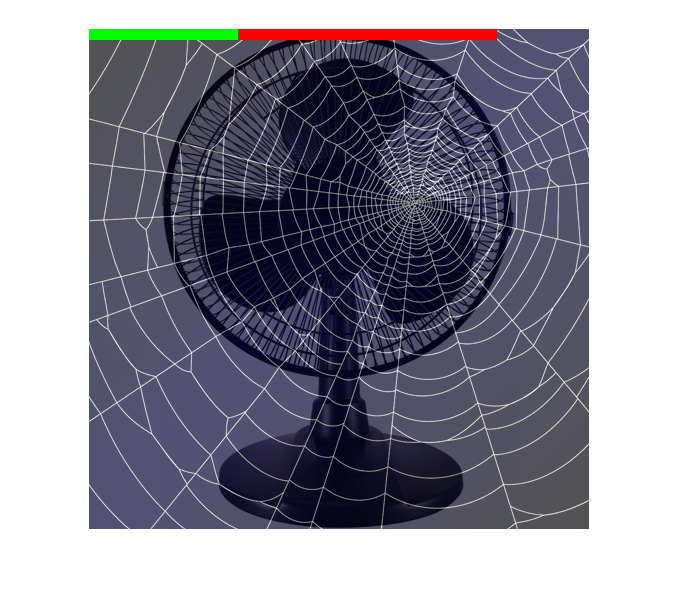


imshow(V2)

E - cyklus s promennou hodnotou R

y = linspace(0.2,0.4,16);

F - vypsani hodnoty na zlutem podkladu

position = [1 1];
value = y(1);

RGB = insertText(V2, position, value);
imshow(RGB)